# Primer Acercamiento a la Interpolación 2D

## Supongamos que dentro de un espacio, ya sea un dato que tiene como coordenadas latitud y longitud, por dar un ejemplo, no se encuentra disponible, está erroneo o simplemente no es válido, ese dato podría ser contado como NaN, indicando una pérdida de dato en ese espacio.

#### Pues bien, una primera aproximación a interpolar ese dato, es obtener ese valor mediante los datos de las columnas y filas más cercanas

Sea una matriz:

## A=$\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
4 & \mathrm{NaN} & 6\\
7 & 8 & 9
\end{array}\right\rbrack$

A=[1 2 3;4 NaN 6; 7 8 9];

#### Y queremos interpolar el dato faltante, es decir A(2,2)

#### Un pimer método, sería darle un peso a cada fila y columna más cercana, es decir, otorgarle una ponderacińn al promedio de cada una.

A(2,2)=0.5*mean(A(2,:),"omitnan")+0.5*mean(A(:,2),"omitnan")

A =      1     2     3
     4     5     6
     7     8     9


En este caso, utilizamos una ponderación de 0.5 para el promedio de los datos más cercanos al NaN ingresando desde las filas y 0.5 para el promedio de los datos más cercanos al NaN ingresando desde las columnas

### Intente automatizar esta idea en una función, en donde debe ingresar la matriz,los pesos de las columnas y las filas, y la ubicación del NaN.

ejemplo

### **function dato = interpolacion2d(MATRIZ,peso_fila,peso_columna,[i j])**

### **end**

# **MÉTODO 2**

**Otro método conocido para la interpolación 2D, es acercarse al valor NaN mediante cajas, y cada caja tendrá una ponderación o peso asignada**

**Ejemplo:**

**B=**$\left\lbrack \begin{array}{ccccc}
1 & 2 & 3 & 4 & 5\\
6 & 7 & 8 & 9 & 10\\
11 & 12 & \textrm{NaN} & 14 & 15\\
16 & 17 & 18 & 19 & 20\\
21 & 22 & 23 & 24 & 25
\end{array}\right\rbrack$

B=[1 2 3 4 5; 6 7 8 9 10; 11 12 NaN 14 15; 16 17 18 19 20; 21 22 23 24 25];

## 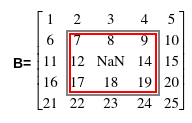 Caja más cercana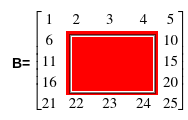**Caja más lejana**

Entonces, lo que se debe realizar, es un promedio de la primera caja, asignarle un peso, y lo mismo para la caja más lejana.

[i j]=find(isnan(B))

i = 3

j = 3

Una vez localizado el NaN

caja_cercana=B(i-1:i+1,j-1:j+1)

caja_cercana =      7     8     9
    12   NaN    14
    17    18    19


Se le saca el promedio a eso:

caja_cercana_prom= mean(caja_cercana(:),"omitnan")

caja_cercana_prom = 13

Ahora bien, para calcular el promedio de la caja más lejana, se puede realizar lo siguiente:

caja_lejana=B;
caja_lejana(i-1:i+1,j-1:j+1)=NaN

caja_lejana =      1     2     3     4     5
     6   NaN   NaN   NaN    10
    11   NaN   NaN   NaN    15
    16   NaN   NaN   NaN    20
    21    22    23    24    25


caja_lejana_prom=mean(caja_lejana(:),"omitnan");

Por lo que, otorgandole, por ejemplo, una ponderación del 80% a la primera caja y una ponderación del 20% a la segunda caja:

B(i,j)=0.8*caja_cercana_prom+0.2*caja_lejana_prom

B =      1     2     3     4     5
     6     7     8     9    10
    11    12    13    14    15
    16    17    18    19    20
    21    22    23    24    25
